# 数值计算 上机作业 Chapter4

### 李宇豪    21305412

对于矩阵

A = [9, 4.5, 3; -56, -28, -18; 60, 30, 19]

A =     9.0000    4.5000    3.0000
  -56.0000  -28.0000  -18.0000
   60.0000   30.0000   19.0000


## （a）任选方法计算矩阵的所有特征值

### 使用 Jacobi 方法计算特征值

%jacobi_fun(A)

由于Jacobi 方法仅对实对称矩阵有效，这里它不收敛

### 使用基于Householder 变换法的 QR 方法计算特征值

[Q, R] = Householder_QR(A)

Q =     0.1090   -0.9935   -0.0343
   -0.6783   -0.0491   -0.7332
    0.7267    0.1032   -0.6792


R =    82.5651   41.2826   26.3428
    0.0000    0.0000   -0.1359
   -0.0000   -0.0000    0.1904


特征值为

diag(R)

ans =    82.5651
    0.0000
    0.1904


### 使用MATLAB自带的QR函数来计算特征值（进行对比验证）

[D, M] = qr(A)

D =    -0.1090   -0.9560    0.2724
    0.6783    0.1288    0.7235
   -0.7267    0.2636    0.6344


M =   -82.5651  -41.2826  -26.3428
         0    0.0000   -0.1777
         0         0   -0.1521


特征值为

diag(M)

ans =   -82.5651
    0.0000
   -0.1521


发现这两种qr分解得到的第三个特征值有一定的差异，我们验证一下精度

norm(A-Q*R)

ans = 3.2904e-14

norm(A-D*M)

ans = 1.2070e-14

从这里可以看到，实际上我们自己写的qr函数与MATLAB自带的qr函数的精度都是非常高的，并且二者的精度差异不大（至少在 $10^{-13}$ 量级），但是分解得到的第三个特征值却在 $10^{-2}$ 量级上就出现了差异。这里的原因与下一小题要研究的内容相同，我们将一并讨论。

## （b）矩阵右下角元素的摄动对特征值的影响

设置

A1 = [9, 4.5, 3; -56, -28, -18; 60, 30, 19.05]

A1 =     9.0000    4.5000    3.0000
  -56.0000  -28.0000  -18.0000
   60.0000   30.0000   19.0500


A2 = [9, 4.5, 3; -56, -28, -18; 60, 30, 18.95]

A2 =     9.0000    4.5000    3.0000
  -56.0000  -28.0000  -18.0000
   60.0000   30.0000   18.9500


然后分别用QR分解计算特征值

[~, R1] = qr(A1);
diag(R1)

ans =   -82.5651
    0.0000
   -0.1203


[~, R2] = qr(A2);
diag(R2)

ans =   -82.5651
    0.0000
   -0.1838


可以看到，第一个和第二个特征值不变，第三个特征值变化较大。

## （c）分析

### 现象分析

经过（a）（b）两个小节我们发现矩阵的第三个特征值似乎是特别“敏感”的。

我们分别对比三个特征值对右下角元素摄动的响应

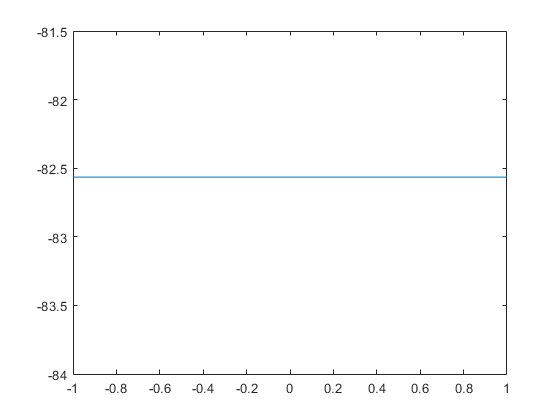

G1 = []; G2 = []; G3 = [];
F = A;
for i = linspace(-1,1,100)
    F(3,3) = A(3,3) - i;
    [~,RF] = qr(F);
    value = diag(RF);
    G1(end+1) = value(1);
    G2(end+1) = value(2);
    G3(end+1) = value(3);
end
% 第一个特征值对右下角元素摄动的响应
plot(linspace(-1,1,100), G1)

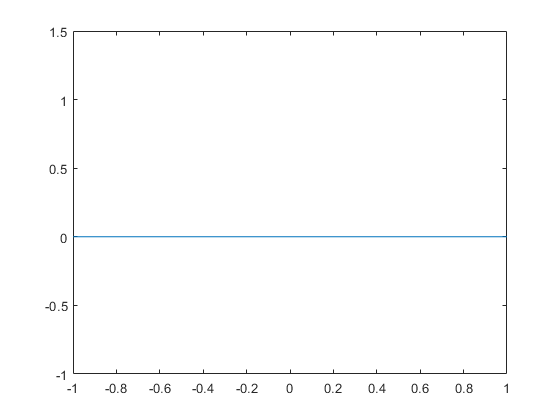

% 第二个特征值对右下角元素摄动的响应
plot(linspace(-1,1,100), G2)

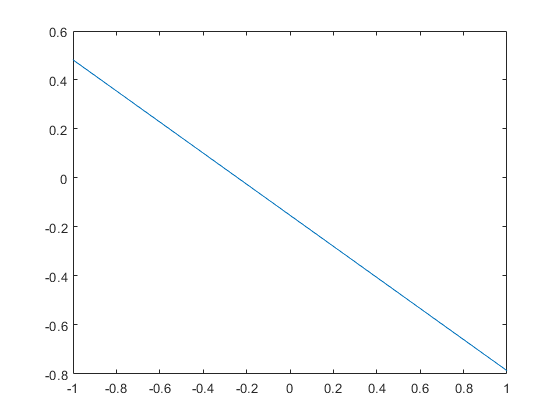

% 第三个特征值对右下角元素摄动的响应
plot(linspace(-1,1,100), G3)

可以看到，确实如我们猜测的那样，第一个和第二个特征值对右下角元素的摄动没有响应，而第三个特征值对右下角元素的摄动有较大响应。

### 原因分析

我们首先观察一下矩阵的奇异性，这里使用条件数倒数而不是行列式来度量奇异性（原因可见MATLAB帮助文档“rcond”词条的示例二，这里展示了一个行列式接近于零但是矩阵条件设置非常良好且不接近奇异矩阵的例子）

rcond(A)

ans = 2.2204e-18

可以看到，A矩阵是奇异的，从这里看，似乎特征值对矩阵右下角元素摄动的较大响应该归因于这个矩阵是病态的。

但是我们接下来展示一个例子

将 A 矩阵的前两列都缩小100倍

F = A;
F(:,[1,2]) = F(:,[1,2])/100;

我们再观察一下 F 的奇异性

rcond(F)

ans = 3.4694e-20

可以看到，这个矩阵仍是奇异的。但是我们考察 F 的第三个特征值对右下角元素的摄动

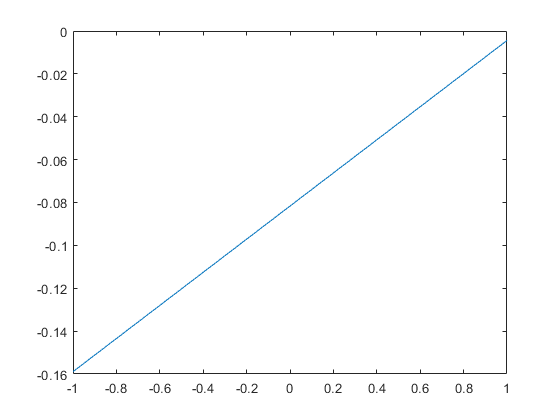

G3 = [];
for i = linspace(-1,1,100)
    F(3,3) = A(3,3) - i;
    [~,RF] = qr(F);
    value = diag(RF);
    G3(end+1) = value(3);
end
% 第三个特征值对右下角元素摄动的响应
plot(linspace(-1,1,100), G3)

发现此时第三个特征值对右下角元素的摄动的响应变小了很多（大约小了3~4倍），这个响应似乎与矩阵前两列的数值设置也有一定关系

下面我们将矩阵改为非奇异的

H = A;
G(2,2) = H(2,2) + 0.1;
rcond(H)

ans = 2.2204e-18

矩阵（相比于A）已经不是那么病态了，但是考察特征值对右下角元素的摄动的响应

G3 = [];
for i = linspace(-1,1,100)
    H(3,3) = A(3,3) - i;
    [~,RH] = qr(H);
    value = diag(RH);
    G3(end+1) = value(3);
end
% 第三个特征值对右下角元素摄动的响应
plot(linspace(-1,1,100), G3)

可以看到，此时特征值的响应仍然较大，甚至比奇异状态下的 A 都要大。

经过上面的讨论，这个矩阵的第三个特征值对右下角元素摄动的响应不应归因于矩阵是病态的，而是与矩阵前两列元素的设置有关。但是这种影响是不是根本的，我们还不得而知。

## 致谢

感谢20级余荫铠学长在其作业中对本问题的深入分析，其分析的思路对于本文的讨论有很大帮助。

## 附：用到的函数定义

function B = jacobi_fun(A)
flag=1;
while(flag)
    B=A;
    n=size(B,1);
    p=1;q=2;
    for i=1:n
        for j=i+1:n
            if(abs(B(i,j))>abs(B(p,q)))%找到对称矩阵的上三角矩阵中最大的元素的下标
                p=i;q=j;
            end
        end
    end
    if(abs(B(p,q))<1e-9)
        flag=0;%设置精度，达到精度迭代停止
    end
    if(B(p,p)==B(q,q))
        sita=pi/4;
    else
        sita=1/2*atan(2*A(p,q)/(B(q,q)-B(p,p)));
    end
    c=cos(sita);s=sin(sita);
    A([p,q],:)=[c,-s;s,c]*B([p,q],:);%更新p,q行的
    A(:,[p,q])=B(:,[p,q])*[c,s;-s,c];%更新p,q列的
    A([p,q],[p,q])=[c,-s;s,c]*B([p,q],[p,q])*[c,s;-s,c];%更新p行、q行和p列、q列的相交位置的
end

end

function H = Householder_reduction(x)
% 对于一个向量 x，求出一个Householder矩阵，使得 Hx = k * e1，k > 0

k = norm(x);  % 向量 x 的模长
n = length(x);
e1 = zeros(n, 1);
e1(1) = 1;
w = x - k * e1;

H = eye(n) - 2 * (w * w') / (norm(w) ^ 2);

end

function [Q, R] = Householder_QR(A)
% 对可逆矩阵A使用Householder变换进行QR分解

[n, ~] = size(A);
Q = eye(n);
for i = 1 : n - 1
    x = A(i:end,i);
    H = Householder_reduction(x);
    T = eye(n);
    T(i:end, i:end) = H;
    Q = T * Q;
    A = T * A;
end
Q = Q';
R = A;
end